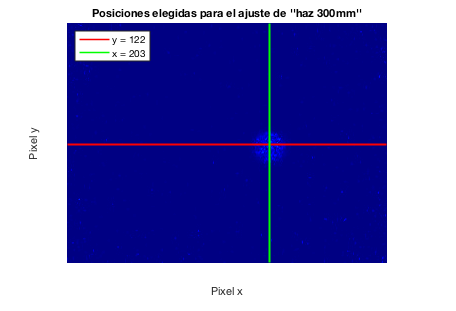

Px =     0.3446    2.2443   22.3742


Py =     0.3595    1.9848   21.7454


I0_prom = 0.3521

w_prom = 22.0598

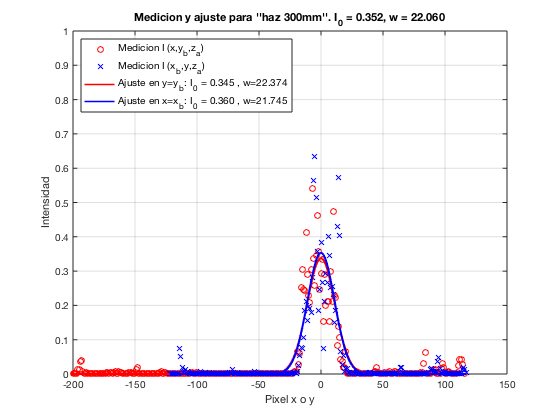

w_prom_z =    22.0600   22.4600   24.1070


w_prom_z = 	1.0e+-3 *

    0.5515    0.5615    0.6027


z =     0.3000    0.3050    0.3100


A_raiz = 	1.0e+-4 *

   0.0015 + 0.6043i
   0.0015 - 0.6043i


A =    0.0055 - 0.0055i   0.0055 - 0.0055i   0.0056 - 0.0056i


w0_al2 =     0.0055    0.0055    0.0056


A_raiz = 	1.0e+-4 *

   0.0016 + 0.6143i
   0.0016 - 0.6143i


A =    0.0055 - 0.0055i   0.0055 - 0.0055i   0.0056 - 0.0056i


w0_al2 =     0.0055    0.0055    0.0056


A_raiz = 	1.0e+-4 *

   0.0018 + 0.6244i
   0.0018 - 0.6244i


A =    0.0055 - 0.0055i   0.0055 - 0.0055i   0.0056 - 0.0056i


w0_al2 =     0.0055    0.0055    0.0056


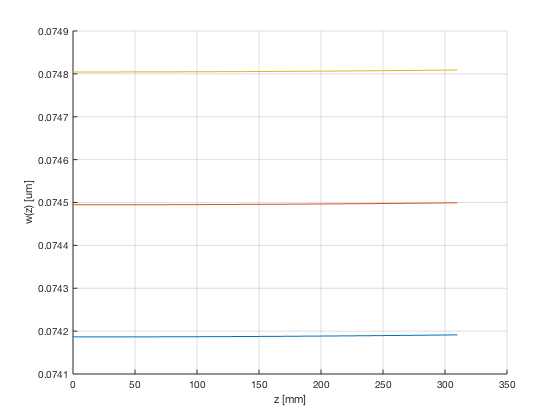

close all;

clear all;

%Carga de imagenes
titulo_img = 'haz_300mm.jpg';%Lo uso para cargar la imagen
titulo_img_graf = 'haz 300mm';%Lo uso de titulo de figura
titulo_img_fig = 'haz_300'; %Lo uso para el nombre al exportar la figura
titulo_img_fig_config = 'libre'; %libre, ancho o angosto, es para exportar

k=65; %iteraciones para buscar el maximo matricial promedio
% Si el centro da mal a ojo, aumentar k 

imagen = im2double(rgb2gray(imread(titulo_img)));
imagen_aux = imagen; %el auxiliar lo necesito para buscar el centro

[fil , col] = size (imagen);

%Esto es para buscar el centro. 
%Busco los primeros K maximos en x e y
%Trabajo sobre una variable auxiliar
for i=1:k
    [Max(i),Ind(i)] = max(imagen_aux(:)); 
    [Ind_fila(i), Ind_col(i)] = ind2sub(size(imagen_aux),Ind(i)); %ind2sub pasa de Ind anterior a los indices fila y columna
    imagen_aux(Ind_fila(i),Ind_col(i))=0; %al maximo encontrado lo borro 
end

%el centro va a estar en los pixels:
fila_max = round( mean(Ind_fila) );
col_max = round( mean(Ind_col) );

%grafico la imagen en falso color y los pixeles 
%xfijo yfijo donde se hara el ajuste
figure();
imshow(gray2ind(imagen), jet());
hold on;
plot(1:(col), fila_max*ones(1,col), "-r", "linewidth", 1.5);
plot(col_max*ones(1,fil), 1:(fil), "-g", "linewidth", 1.5);
title(sprintf('Posiciones elegidas para el ajuste de ''''%s''''',titulo_img_graf));
xlabel('Pixel x');
ylabel('Pixel y');
legend(sprintf('y = %d',fila_max),sprintf('x = %d',col_max),'location','northwest','Fontsize',10);
%print(sprintf('fig_%s_posiciones',titulo_img_fig),'-dpng');


%Para ajustar en el pixel y=cte
med_y = imagen(fila_max,:);
x_0 = 0 : col-1;
x_0 = x_0 - col_max; %le saco la media
%Para ajustar en el pixel x=cte
med_x = transpose( imagen(:,col_max));
y_0 = 0 : fil-1;
y_0 = y_0 - fila_max;

%Ajustes
g = fittype('I0*exp(-2*((x^2+k^2)/w^2))','independent','x','dependent','y');
%en g dice x, pero puede ser x o sino y
fx = fit(x_0.',med_y.',g);
fy = fit(y_0.',med_x.',g);
%Existe warning de semilla no provista
%Puede ser que no ande dependiendo la semilla, volver a poner run

%Nomenclatura: [I0 , b , w] = coeffvalues(f) 
Px = coeffvalues(fx); %Parametros ajustados en x para y=cte
Py = coeffvalues(fy); %Parametros ajustados en y para x=cte

I0_prom = (Px(1) + Py(1))/2 
w_prom = (Px(3) + Py(3))/2 

%Grafico los ajustes y mediciones
figure();
plot(x_0,med_y,'ro',"linewidth", 1.3);
hold on;
grid on;
plot(y_0,med_x,'bx',"linewidth", 1.3);
plot(x_0, Px(1)*exp( - 2*((x_0).^2 + Px(2)^2)/ Px(3)^2 ),'-r', 'linewidth',1.5);
plot(y_0, Py(1)*exp( - 2*((y_0).^2 + Py(2)^2)/ Py(3)^2 ),'-b', 'linewidth',1.5);
title(sprintf('Medicion y ajuste para ''''%s''''. I_0 = %.3f, w = %.3f',titulo_img_graf,I0_prom,w_prom));
xlabel('Pixel x o y');
ylabel('Intensidad');
axis([-200 150 0 1]);
legend('Medicion I (x,y_b,z_a)','Medicion I (x_b,y,z_a)',sprintf('Ajuste en y=y_b: I_0 = %.3f , w=%.3f',Px(1),Px(3)),sprintf('Ajuste en x=x_b: I_0 = %.3f , w=%.3f',Py(1),Py(3)),'location','northwest','Fontsize',10);
%print(sprintf('fig_%s_ajuste',titulo_img_fig),'-dpng');


%Obtencion de w0 a partir de los w_prom a cada distancia 

lambda0 = 632.8E-9; 
pixel = 25E-6; %tamano de cada pixel

% nomenclatura: w_prom_z = [w_prom_300 w_prom_305 w_prom_310]
w_prom_z = [22.060 22.460 24.107]; %estos son pixeles
w_prom_z = w_prom_z * pixel; %w(z) en mm
z_a = [300E-3 305E-3 310E-3]; %posiciones de captura de imagen

%grafico de los w(z) ajustados
%figure()
%plot(z_a,1E6*w_prom_z,'x','LineWidth',2);
%grid on;
%ylabel('w(z) [um]');
%xlabel('z [mm]');

%Obtengo A=w0^2 utilizando la resolvente con la suma de sqrt(discriminante)
%va a haber un w0 que no va a ser logico
%w_0 es real, y no muy distinto a los valores del ajuste
%ya que el haz se ensancha poco en el camino libre

% a x^2 + b x + c = 0
for i=1:3
    a=1;
    b=-w_prom_z(i)^2;
    c=( (z_a(i)*lambda0)/ pi)^2;
    A_raiz_mas(i) = (-b + sqrt(b^2-4*a*c) )/(2*a);
    A_raiz_menos(i) = (-b - sqrt(b^2-4*a*c) )/(2*a);
    w0_mas(i) = sqrt(A_raiz_mas(i));
    w0_menos(i) = sqrt(A_raiz_menos(i));
    %A_raiz_mas(i) = (w_prom_z(i)^2 + sqrt( w_prom_z(i)^4 - 4*((z_a(i)*lambda0) /pi)^2 ))/2;
    %A_raiz_menos(i) = (w_prom_z(i) - sqrt( w_prom_z(i) - 4*((z_a(i)*lambda0) /pi)^2 ))/2;
end

%A_raiz_mas
%A_raiz_menos
w0_mas
%w0_menos
w0_prom = mean(w0_mas)

%Grafico para verificar w(x) con w0 obtenido 
z= 0:0.001:0.310;

figure()
plot(1E3*z_a,1E6*w_prom_z,'x','LineWidth',3);
hold on;
grid on;
plot(1E3*z,1E6*sqrt((w0_prom^2 *( 1+ ( (z*lambda0)/(pi*w0_prom^2) ).^2 ))  ));
for i=1:3    
    plot(1E3*z,1E6*sqrt((w0_mas(i)^2 *( 1+ ( (z*lambda0)/(pi*w0_mas(i)^2) ).^2 ))  ));
end
title('w(z) para w_0 obtenidos del ajustes y el promedio');
ylabel('w(z) [um]')
xlabel('z [mm]')
legend('w(z) dados por ajuste',sprintf('promedio w_0=%.fmm',w0_prom*1E6),sprintf('w_0=%.f a z_a=300mm',w0_mas(1)*1E6),sprintf('w_0=%.f a z_a=305mm',w0_mas(2)*1E6),sprintf('w_0=%.f a z_a=310mm',w0_mas(3)*1E6),'location','best','Fontsize',11);
print(sprintf('fig_w(z)_%s',titulo_img_fig_config),'-dpng');


